--general m

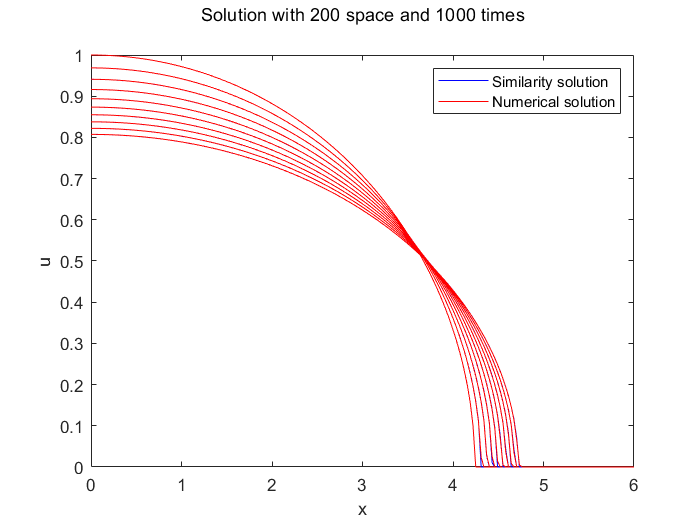

clc;clear;
% Parameters
% see the effect of spreading to a nearly flat pond 
%xf = 6; T = 20;    

% normal spreading
xf = 6; T = 1;

M = 200;      % Number of grid points
N = 1000;
dr = xf / (M-1);   % Spatial step size
dt = T / (N-1);   % Time step size
m = 2;        % Exponent

% Initialize grid
r = [0: 1: M-1]'*dr;
t = [0: 1: N-1]*dt;

% true solution for comparison:
u_simi = @(r,t) max(2*(-1/36.*((r).*((t+1).^(-1/6))).^2+1/2),0).^(1/2).*(t+1).^(-1/3);
Utrue = u_simi(r,t);

% set initial conditions
u0 = u_simi(r,0);
u = u0;
U(:,1) = u0;
%t1 = 0;
% Time evolution
for j=2:N
%while t1<T  
   u=u0;
   %U(:,j)=u;
   for k=1:5  %(newton iterations at each time)
      % Compute Jacobian matrix (a tridiagonal matrix)
      for i = 2:M-1
        F(i) = u(i)-u0(i) - dt * ( (r(i)+0.5*dr) *( u(i+1)^(m+1)-u(i)^(m+1) ) ...
            - (r(i)-0.5*dr) * (u(i)^(m+1)-u(i-1)^(m+1) ) ) / (dr*r(i)*dr) ;
        J(i, i) = 1 - dt * ( ( -(m+1)*(r(i)+0.5*dr)*u(i)^m ) ...
            + ( -(m+1)*(r(i)-0.5*dr)*u(i)^m ) ) / (dr*r(i)*dr);
        J(i, i-1) = -dt * ( (m+1) * (r(i)-0.5*dr) * u(i-1)^m ) / (dr*r(i)*dr);
        J(i, i+1) = -dt * ( (m+1) * (r(i)+0.5*dr) * u(i+1)^m )/ (dr*r(i)*dr);    
      end  % end i 
      
      % Include Neumann BC's in Jacobian (Neumann + Neumann)
       F(1) = ((-3)*u(1) + 4*(u(2)) - u(3));
       F(M) = ((3)*u(M) - 4*(u(M-1)) + u(M-2));
   
       J(1, 1) = (-3);
       J(1, 2) = 4;
       J(1,3) = -1;
       J(M, M) = (3);
       J(M, M-1) = -4;
       J(M,M-2) = (1);
       
       delta_u = -sparse(J) \ F';
       u = u + delta_u;
   end    % end k        
   u0 = u;
   U(:,j)=u;
end    % end j  

figure(1)
% plot solution every N/10 time steps
step = N/10;
for j = 1:step:N
    plot(r, Utrue(:,j),'b');
    hold on;
    plot(r, U(:,j),'r');
end
title(sprintf('Solution with %i space and %i times\n', M ,N));
legend('Similarity solution','Numerical solution');
xlabel('x')
ylabel('u')
hold off; 

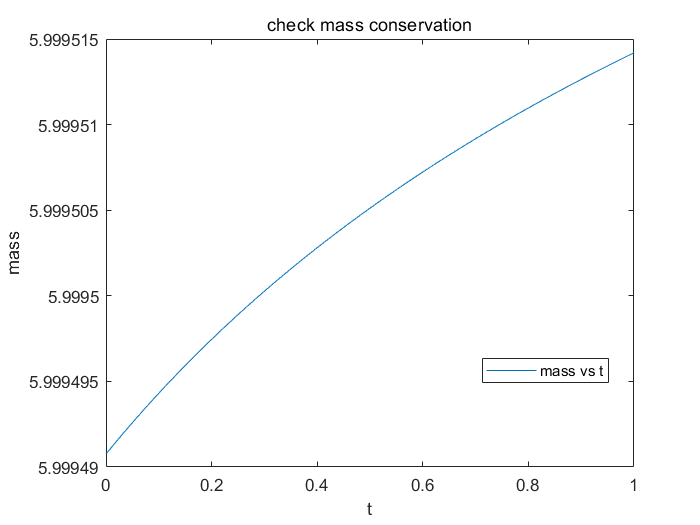


 
for j = 1:N
    u_max(j) = max(U(:,j));
    mass(j) = 0;
    for i = 1:M
    mass(j) =  mass(j) + (r(i)*U(i,j))* dr;
    end
end
plot(t, mass)
title('check mass conservation')
legend('mass vs t')
legend('location','best')
xlabel('t')
ylabel('mass')
hold off


loglog(t,u_max,'O-');
hold on
p = polyfit(t,u_max.^(-3) ,1) %  *-6?

p =     0.9996    1.0000


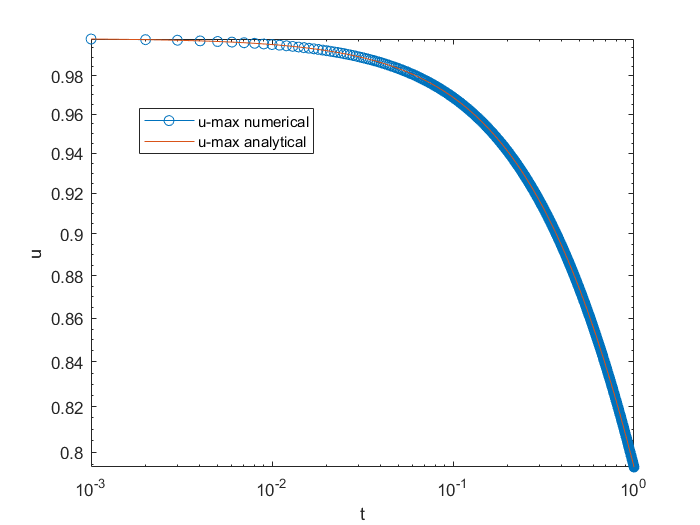

%plot(t,u_max.^(-3))
loglog(t,max(p(1)*(t+p(2)/p(1)),0).^(-1/3));
legend('u-max numerical','u-max analytical');
legend('location','best')
xlabel('t')
ylabel('u')
hold off